# 信号频谱分析

## 背景知识：傅里叶变换基础

### 1 傅里叶级数（CTFS）

时域周期 <-> 频域离散

- 基频 $\Omega_0=2\pi/T_0$

- 正向变换 $X_k = \frac{1}{T_0} \int_0^{T_0} x(t) e^{-jk\Omega_0 t} dt$

- 逆向变换 $x(t) = \sum_{k=-\infty}^{\infty} X_k e^{jk\Omega_0 t}$

- 帕塞瓦尔定理 $\frac{1}{T_0}\int_0^{T_0} |x(t)|^2 dt = \sum_{k=-\infty}^{\infty} |X_k|^2$

### 2 连续时间傅里叶变换（CTFT）

时域无穷、没有周期性 <-> 频域连续

时域连续 <-> 频域无穷

- 正向变换 $X(j\Omega)=\int_{-\infty}^{\infty}x(t)e^{-j\Omega t} dt$

- 逆向变换 $x(t) = \frac{1}{2\pi} \int_{-\infty}^{\infty} X(j\Omega) e^{j\Omega t} d\Omega$

- 帕塞瓦尔定理 $\int_{-\infty}^{\infty} |x(t)|^2 dt = \frac{1}{2\pi} \int_{-\infty}^{\infty} |X(j\Omega)|^2 d\Omega$

### 3 离散时间傅里叶变换（DTFT）

时域无穷、没有周期性 <-> 频域连续

时域离散 <-> 频域有限、周期

- 正向变换 $X(j\omega)=\sum_{n=-\infty}^{\infty} x_n e^{-j\omega n}$

- 逆向变换 $x_n = \frac{1}{2\pi} \int_{0}^{2\pi} X(j\omega) e^{j\omega n} d\omega$

- 帕塞瓦尔定理 $\sum_{k=-\infty}^{\infty} |x_n|^2 = \frac{1}{2\pi}\int_0^{2\pi} |X(j\omega)|^2 dt$

### 4 离散傅里叶变换（DFT）

时域有限、周期 <-> 频域离散

时域离散 <-> 频域有限、周期

- 基频 $\omega_0=2\pi/N$

- 正向变换 $X_k = \sum_{n=0}^{N-1} x_n e^{-jk\omega_0 n}$

- 逆向变换 $x(t) =\frac{1}{N} \sum_{k=0}^{N-1} X_k e^{jk\omega_0 n}$

- 帕塞瓦尔定理 $\sum_{n=0}^{N-1} |x_n|^2 = \frac{1}{N} \sum_{k=0}^{N-1} |X_k|^2$

## Create time signal

fs = 500;
t = 0:1/fs:5-1/fs;
freq = 0:fs/length(t):fs-1/fs;
A = [1 4];      % Amplitude
f = [100; 110]; % Frequency

xn = A*sin(2*pi*f*t);
N = length(xn); % Number of samples

## 频谱=幅度谱+相位谱，通过频谱获得信号幅度

对于一个正弦信号$x(t) = Asin(2\pi f_0t)$，按照采样间隔$T_s$进行采样，得到采样信号$x_n = Asin(2\pi f_0/f_s n)$，对这个信号进行DFT


$$X_k 
= \sum_{n=0}^{n=N-1} x(n) e^{j \frac{2\pi}{N}nk} 
= A\sum_{n=0}^{n=N-1} 
\left( 
sin(2\pi f_0/f_s n) \cdot cos(\frac{2\pi}{N}nk) 
- sin(2\pi f_0/f_s n) \cdot sin(\frac{2\pi}{N}nk) 
\right)$$


当归一化信号频率$2\pi f_0/f_s = \frac{2\pi}{N}nk$时，由于$sin\alpha \cdot cos\alpha=1/2 \cdot sin2\alpha$，$sin\alpha \cdot sin\alpha=1/2(1-cos2\alpha)$，当N取值足够大时，可以得到

$\frac{|X_k|}{N}=\frac{A}{2}$，这里的1/2来源于信号幅度在正负频率上被均分

当归一化信号频率$2\pi f_0/f_s \neq \frac{2\pi}{N}nk$时，右侧的累加项具有周期性，且它的和有界


$$\frac{|X_k|}{N}=0$$


## Amplitude Spectrum from FFT

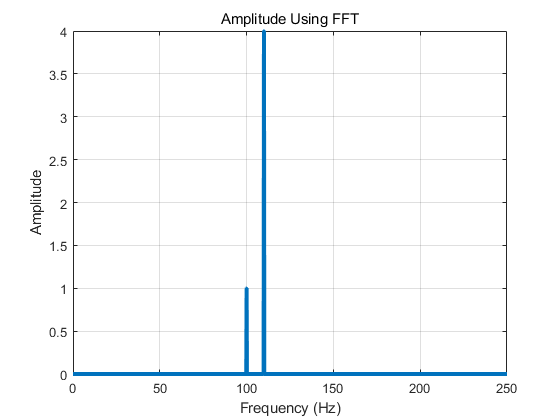

xk = abs(fft(xn))/N; % Two-sided amplitude
xk = xk(1:N/2+1); % One-sided
xk(2:end-1) = 2*xk(2:end-1); % Double values except for DC and Nyquist

figure
plot(freq(1:N/2+1),xk, 'LineWidth', 3)
grid on
title("Amplitude Using FFT")
xlabel("Frequency (Hz)")
ylabel("Amplitude")

## 功率谱

正弦信号$x(t) = Asin(2\pi f_0t)$，其功率为$\frac{A^2}{2}$

双边功率谱$PS = \left( \frac{|X_k|}{N} \right)^2=\frac{A^2}{4}$，信号功率在正负频率上被均分

## Power Spectrum from FFT

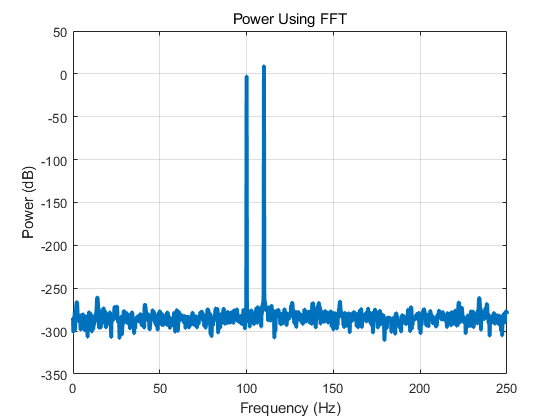

xk = (1/N^2)*abs(fft(xn)).^2; % Two-sided power
xk = xk(1:N/2+1); % One-sided
xk(2:end-1) = 2*xk(2:end-1); % Double values except for DC and Nyquist

figure
plot(freq(1:N/2+1),pow2db(xk), 'LineWidth', 3)
grid on
title("Power Using FFT")
xlabel("Frequency (Hz)")
ylabel("Power (dB)")

This is exactly what the periodogram function produces.

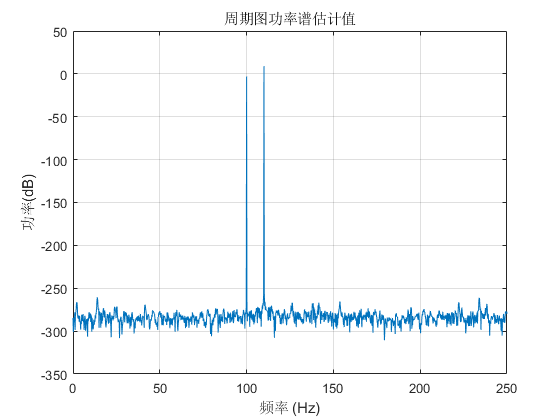

periodogram(xn, rectwin(length(xn)), length(xn), fs, 'power')

Periodogram also takes into account the window and the FFT length when calaculating power. Notice the peak power is the same dispite using a Hamming window and a longer length FFT (zero padded).

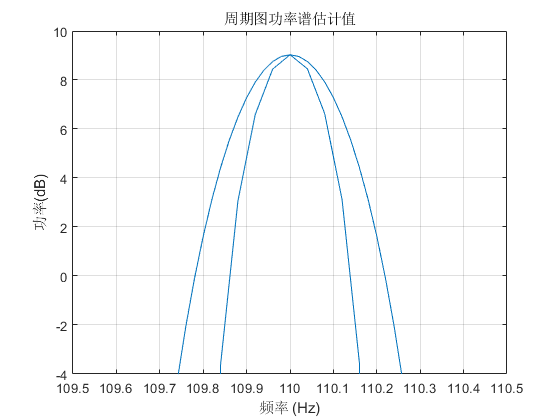

figure
periodogram(xn, rectwin(length(xn)), length(xn)*5, fs, 'power')
hold on
periodogram(xn, hamming(length(xn)), length(xn)*10, fs, 'power')
axis([109.5, 110.5, -4, 10])

## 功率谱密度，衡量一个频率窗口内频率贡献强度

由于施加窗函数导致的频谱泄露，对于宽带信号，在一个频点上的功率谱强度并非表示的是这个频点的功率，而是在频率窗口和所有频率上功率进行积分的结果。这个频率窗口定义为等效噪声带宽（ENBW）

频率谱密度定义PSD=PS/ENBW


$$PS=\frac{|FFT|^2}{N^2}$$



$$ENBW=f_s \frac{\sum_n |w(n)|^2}{|\sum_n w(n)|^2}$$


对于矩形窗口，$ENBW = f_s/N$，$PSD = |FFT|^2/(Nf_s)$

正弦信号$x(t) = Asin(2\pi f_0t)$，其功率为$\frac{A^2}{2}$

双边功率谱$PS = \left( \frac{|X_k|}{N} \right)^2=\frac{A^2}{4}$，信号功率在正负频率上被均分

## Power Spectral Density from the FFT

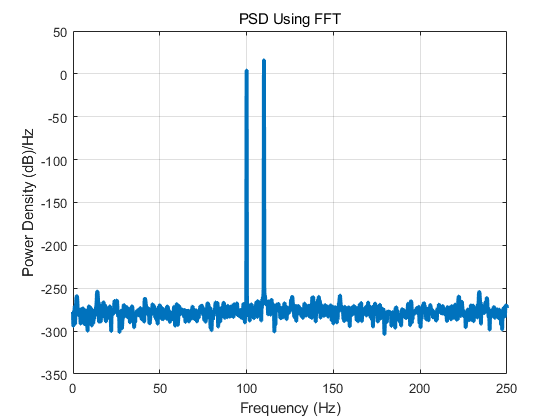

xk = (1/(fs*N))*abs(fft(xn)).^2; % Two-sided power
xk = xk(1:N/2+1); % One-sided
xk(2:end-1) = 2*xk(2:end-1); % Double values except for DC and Nyquist

figure
plot(freq(1:N/2+1),pow2db(xk), 'LineWidth', 3)
grid on
title("PSD Using FFT")
xlabel("Frequency (Hz)")
ylabel("Power Density (dB)/Hz")

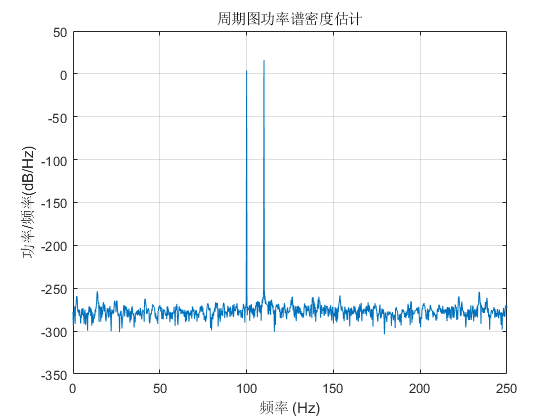

periodogram(xn, rectwin(length(xn)), length(xn), fs, 'psd');